# Homework Assignment - Daniel Kuknyo [Y80L35]

## Remove people from photos / video

Implement a method to remove people and other non-stationary objects from your images taken at the same moment and place, and from webcam streams. 

Normalize the images before processing, take the intensity variation due to shading and day-light-cycle into account. 

You may also consider registering the images to suppress the shaking of the camera (not expected). 

The expected output is a single image (from images or video frames) with the moving objects removed.

## Read dimensions of the Video 

First, we will try the median filtering on a video, taken on the Dobó tér of Eger. If it works on a video, it should work on anything. This code will let us know all the dimesnsions to work with.

% Get the dimensions of the video
name = 'egermjv20161020.webm';
v = VideoReader([name]);

dims = [];
len_video = 1; % Determine how many frames are there

while hasFrame(v)
    if len_video == 1
        frame = readFrame(v);
        dims = size(frame);
        if(dims(1) > 800)
            frame = imresize(frame, 0.33); % If the image is too large, decrease it to 1/3 of it's size
        end
        dims = size(frame); % Get the size of the image
    else
        readFrame(v);
    end
    len_video = len_video+1; % Count how many frames we are working with
end

## Read the video into a matrix so we can start off from there

A 4D matrix will contain our 3-channel RGB images. First we will test it out with a small batch size

v = VideoReader([name]); % Re-initialize video reader from 1st frame
batch_size = 10; % how many images to read
start = 2000; % index of 1st frame to read 
stop = start+batch_size; % index of last image to read

frames = run_on_batch(batch_size, dims, start, stop, v, len_video);

## Let's test out how a normalized image looks

Pretty much what I wanted to see. It seems that the colors are kept true to the original ones. We can also see that the image is resized. 

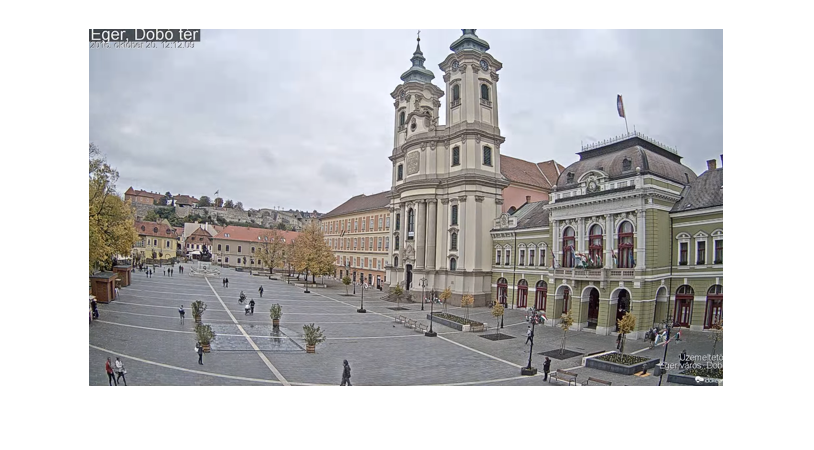

imshow(squeeze(frames(1, :, :, :)));

## Now run the median filter to iterate through the first batch of images

This will take a bit of time. The result is a single image, filtered. No gamma correction will be applied yet. 

img_filt = med_filt(frames);

## The result of median filtering compared to a video frame

Resolution might be worse than the original, but we win runtime! In these images we can see people removed from just 50 images, from the middle of the video. We can observe that moving objects were removed. The image looks grayish because it's an autumn day, october 19. This requires further investigation. 

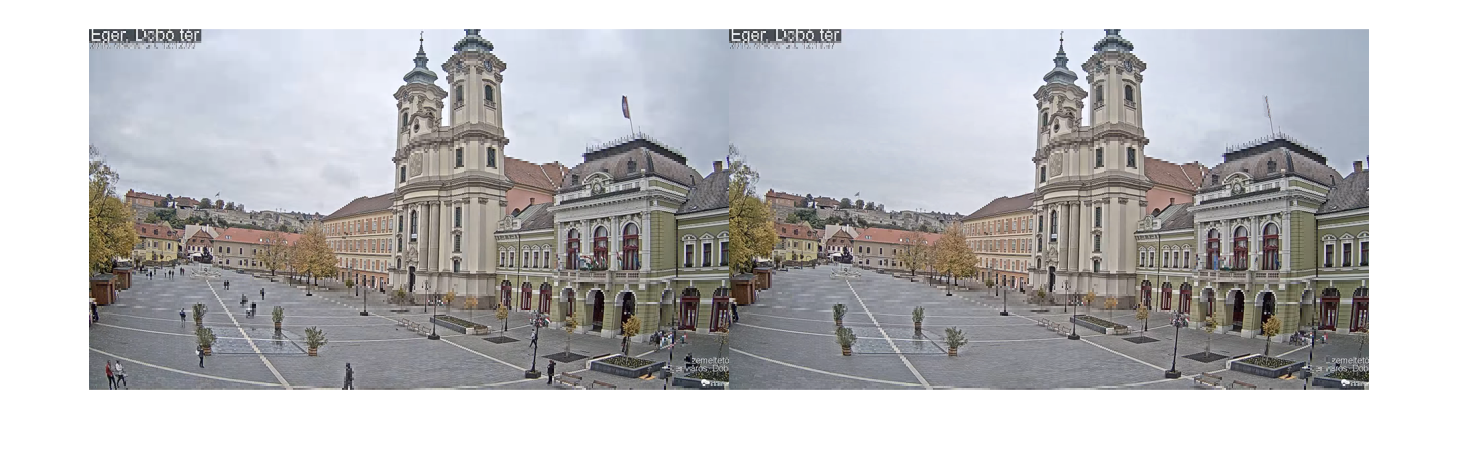

I1 = squeeze(frames(1, :, :, :));
figure, montage({I1, img_filt}, 'Size', [1, 2])

## Let's run median filtering on all images with Gamma correction

This will create evenly spaced batches of frames, and run median filtering on each batch, resulting in a batch of median filtered frames. Gamma correction is applied on the images a after a batch is median filtered. 

v = VideoReader(name);
cumulated_batch = run_on_video(v, len_video, dims, -1);

Finished batch:
     1

Finished batch:
     2

Finished batch:
     3

Finished batch:
     4

Finished batch:
     5

Finished batch:
     6

Finished batch:
     7

Finished batch:
     8

Finished batch:
     9

Finished batch:
    10

Finished batch:
    11

Finished batch:
    12

Finished batch:
    13

Finished batch:
    14

Finished batch:
    15

Finished batch:
    16

Finished batch:
    17

Finished batch:
    18

Finished batch:
    19

Finished batch:
    20

Finished batch:
    21

Finished batch:
    22

Finished batch:
    23

Finished batch:
    24

Finished batch:
    25

Finished batch:
    26

Finished batch:
    27

Finished batch:
    28

Finished batch:
    29

Finished batch:
    30

Finished batch:
    31

Finished batch:
    32

Finished batch:
    33

Finished batch:
    34

Finished batch:
    35

Finished batch:
    36

Finished batch:
    37

Finished batch:
    38

Finished batch:
    39

Finished batch:
    40

Finished batch:
    41

Finished batch:


j = 1

Finished batch:
    64



## As that's done, we have to run median filtering on the median filtered batches

This step is to apply th median filter on the median filtered images of the batches. With this step we will get the final, individual image in the end.

img_final = med_filt(cumulated_batch);

img_final_corr = gamma_correct(img_final); % We have to apply a last bit of gamma correction, as the cumulated batch is made up of different images aswell

## Save and display the images

imwrite(img_final_corr,'final_medfilt.jpg');
writematrix(img_final_corr,'img_final_tab.txt','Delimiter','tab');

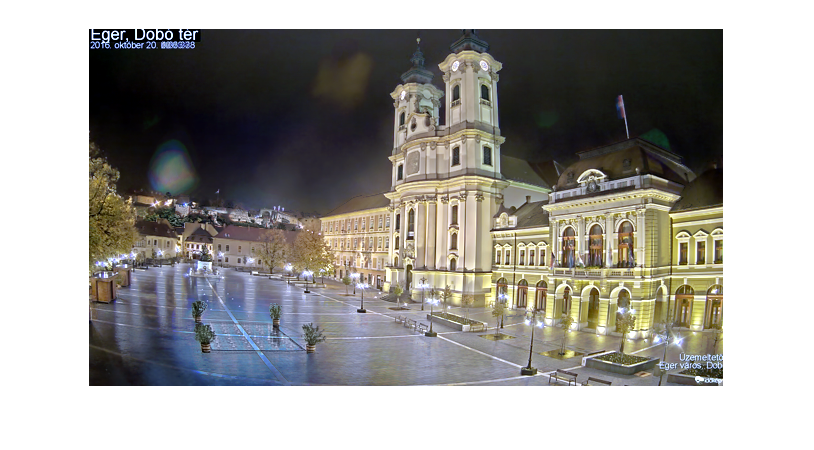

imshow(img_final_corr);

## Now, try for a different video

This time there will be more sun in the video, and more moving people as we are looking at one of the busiest summer days on july 19. We aren't including the sunset this time, the last few hundred frames of the video (total of 57/65 batches were used). To run this, the dimensions of the other video has to be read, to know the variables dims, len_video (for batching).

name = 'egermjv20160729.webm';
v = VideoReader(name);
cumulated_half = run_on_video(v, len_video, dims, 57);

Finished batch:
     1

Finished batch:
     2

Finished batch:
     3

Finished batch:
     4

Finished batch:
     5

Finished batch:
     6

Finished batch:
     7

Finished batch:
     8

Finished batch:
     9

Finished batch:
    10

Finished batch:
    11

Finished batch:
    12

Finished batch:
    13

Finished batch:
    14

Finished batch:
    15

Finished batch:
    16

Finished batch:
    17

Finished batch:
    18

Finished batch:
    19

Finished batch:
    20

Finished batch:
    21

Finished batch:
    22

Finished batch:
    23

Finished batch:
    24

Finished batch:
    25

Finished batch:
    26

Finished batch:
    27

Finished batch:
    28

Finished batch:
    29

Finished batch:
    30

Finished batch:
    31

Finished batch:
    32

Finished batch:
    33

Finished batch:
    34

Finished batch:
    35

Finished batch:
    36

Finished batch:
    37

Finished batch:
    38

Finished batch:
    39

Finished batch:
    40

Finished batch:
    41

Finished batch:


img_final_half = med_filt(cumulated_half);
img_final_corr_half = gamma_correct(img_final_half);

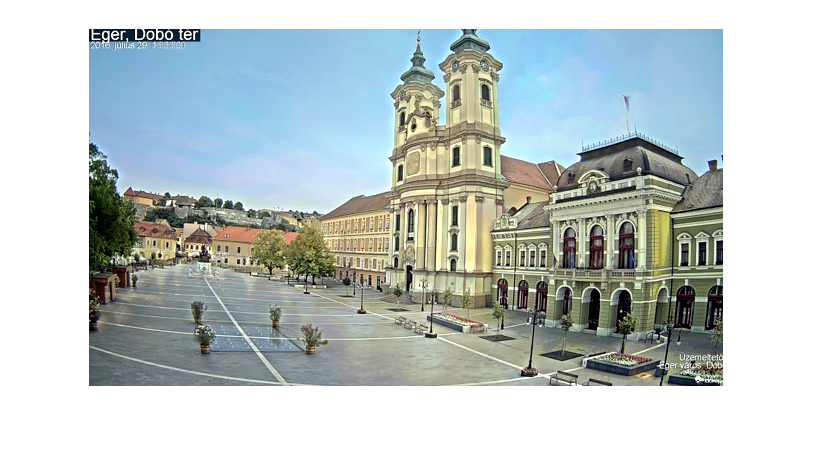

imshow(img_final_corr_half); 

## Results

As we can see the algorithm removes moving objects nicely from videos, resulting in well-balanced images. On a winter day, when most of the day it's dark outside, the median image will result in a nighttime frame. On summer days, when most of the day is spent in sunlight, the end image is sunny, with clear skies. 

In none of the cases had the algorithm result in a cloudy image. 

## Functions used

Each function has a description next to it, as well as key details regarding program logic

function cumulated_batch = run_on_video(v, len_video, dims, max_batch) % Run median filter in batches, return the median filtered batch
    batch_size = floor(sqrt(len_video));
    num_batches = -1; % This is never a possibility
    if max_batch == -1 
        num_batches = batch_size + 1; % No cropping used
    else
        num_batches = max_batch; % Crop video until max_batch
    end
    
    cumulated_batch = zeros(num_batches, dims(1), dims(2), dims(3));
    frames = zeros(batch_size, dims(1), dims(2), dims(3));
    
    bcount = 1; % Batch counter
    fcount = 1; % Frame counter
    icount = 1; % Image counter
    
    while hasFrame(v)
        if fcount > batch_size | icount == len_video
            if icount == len_video % Reached the end of video
                j=1;
                for k=1:batch_size
                    if isequal(squeeze(frames(k,:,:,:)), zeros(dims(1),dims(2),dims(3)));
                        break
                    end
                    j=j+1;
                end
                frames = frames(1:j,:,:,:);
            end
            img_filt = med_filt(frames);
            img_filt = gamma_correct(img_filt); % Gamma correction on all channels of the individual images
            cumulated_batch(bcount,:,:,:) = img_filt;
            frames = zeros(batch_size, dims(1), dims(2), dims(3));
            disp('Finished batch:')
            disp(bcount);
            bcount = bcount+1;
            fcount = 1;
            if bcount == max_batch
                break
            end
        else
            frame = readFrame(v);
            frame = imresize(frame, [dims(1), dims(2)]);
            frame = normalize_img(frame);
            frames(fcount, :, :, :) = frame; 
            fcount = fcount+1;
        end
        icount = icount+1;
    end
end

%-----------------------------------------------------------------------------------------------------------------------
function frames = run_on_batch(batch_size, dims, start, stop, v, len_video) % Run median filtering from/to a given frame in the video
    i = 1; % index of all images
    fcount = 1; % index of the current image in frames variable
    
    if stop <= len_video
        frames = zeros(batch_size, dims(1), dims(2), dims(3)); % This array will store all the data of the video: images, width, height channel
    end
    
    while hasFrame(v)
        if i < start
            readFrame(v);
        else
            frame = readFrame(v);
            frame = imresize(frame, [dims(1), dims(2)]);
            frame = normalize_img(frame);
            frames(fcount, :, :, :) = frame;
            fcount = fcount+1;
            
            if i == stop
                break
            end
        end
        i = i + 1;
    end
end

%-----------------------------------------------------------------------------------------------------------------------
function img_corr = gamma_correct(img) % Run gamma correction on a 3-channel RGB image, each channel individually
    isize = size(img);
    img_corr = zeros(isize(1), isize(2), isize(3));
    for i = 1:3
        adj_channel = imadjust(squeeze(img(:,:,i))); 
        img_corr(:,:,i) = adj_channel;
    end
end

%-----------------------------------------------------------------------------------------------------------------------
function normed_img = normalize_img(img) % Normalize a h * w * 3 RGB image 
    imsize = size(img);
    normed_img = zeros(imsize);
    
    for i = 1:3
        im_channel = double(squeeze(img(:,:,i)));
        im_channel = im_channel - min(im_channel(:));
        im_channel = im_channel / max(im_channel(:));
        normed_img(:,:,i) = im_channel;
    end
end
 
%-----------------------------------------------------------------------------------------------------------------------
function filt_img = med_filt(batch) % Median filter of a batch of images, input: batch_size * w * h * 3 matrix
    bsize = size(batch); % IMAGE, HEIGHT, WIDTH, CHANNEL
    num_img = bsize(1);
    height = bsize(2);
    width = bsize(3);
    channels = 3;
    filt_img = zeros(bsize(2), bsize(3), bsize(4), 'double'); % This will be the result
    
    for h = 1:height
        for w = 1:width
            for c = 1:channels
                arr = get_array(batch, h, w, c); % Get the array of corresponding H, W pixel RGB 
                med = calc_median(arr); % Calculate the median of the array
                filt_img(h, w, c) = med; % Overwrite the corresponding channel of pixel in result image
            end
        end
    end
end

%-----------------------------------------------------------------------------------------------------------------------
function result = get_array(batch, h, w, c) % Returns an array of color coordinates from a batch
    bsize = size(batch);
    num_img = bsize(1);
    result = zeros(1, num_img);
    for i = 1:num_img
        result(1, i) = batch(i, h, w, c);
    end
end

%-----------------------------------------------------------------------------------------------------------------------
function y = calc_median(x) % A function to take the median of the array passed to it. Input: a row vector n>2
    arrsize = size(x);
    arrsize = arrsize(2);
    arr_sorted = merge_sort(x);
    if(arrsize < 2)
        disp('Not enough elements in array (need n>2)');
        return
    end
    if mod(arrsize, 2) == 1 % Odd number of elements
        ind = round(arrsize/2);
        y = arr_sorted(ind);
    elseif mod(arrsize, 2) == 0 % Even number of elements
        elem1 = arr_sorted(arrsize/2);
        elem2 = arr_sorted(arrsize/2 + 1);
        y = (elem1 + elem2) / 2;
    end
end

%-----------------------------------------------------------------------------------------------------------------------
function y = merge_sort(x) % A recursive merge sort implementation (needed for median calculation)
    n = length(x);
    if(n < 2) % Return Condition
        y=x;
        return;
    end
    
    n_2 = int32(n/2);
    x1=merge_sort(x(1:n_2));
    x2=merge_sort(x(n_2+1:n));
    n1 = length(x1);
    n2 = length(x2);
    count_x1 = 1;
    count_x2 = 1;
    y = [];
    
    while(count_x1 <= n1)
        if(count_x2 > n2)
            y = [y x1(count_x1)];
            count_x1 = count_x1 + 1;
            continue;
        end
        if(x1(count_x1) > x2(count_x2))
            y = [y x1(count_x1)];
            count_x1 = count_x1+1;
        else
            y = [y x2(count_x2)];
            count_x2 = count_x2+1;
        end
    end
    for j=count_x2:n2
        y = [y x2(j)];
    end
end